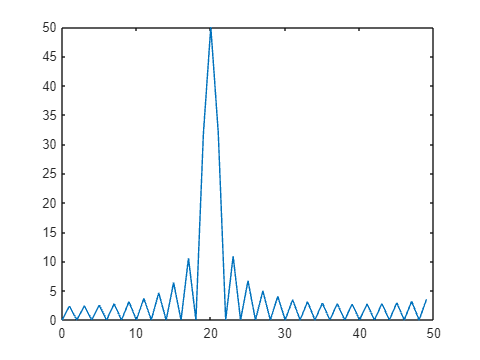

N = 100;
fs = 100;
f1 = 30;
f2 = 10;
t = (0:N-1)/fs;
y2 = zeros(1, 200);
y1 = sin(2*pi*f1*t) + sin(2*pi*f2*t);
y2(1:100) = sin(2*pi*f1*t);
y2(101:end) = sin(2*pi*f2*t);
Y1=fft(y1);
Y2=fft(y2);
f = fs/N*(0:N/2-1);
figure()
% plot(f,abs(Y1(1:fs/2))), hold on
plot(f,abs(Y2(1:fs/2)))